%% Parameterize the arm
rho = 0.0254; % M, Radius
 
% Construct pose matrices
% Transform from world frame to base curve
g_o = SE2(0, 0, pi/2);

g_o_A = SE2(0, rho, 0);
g_o_B = SE2(0, -rho, 0);

l_0 = 18*0.0254; % Default length

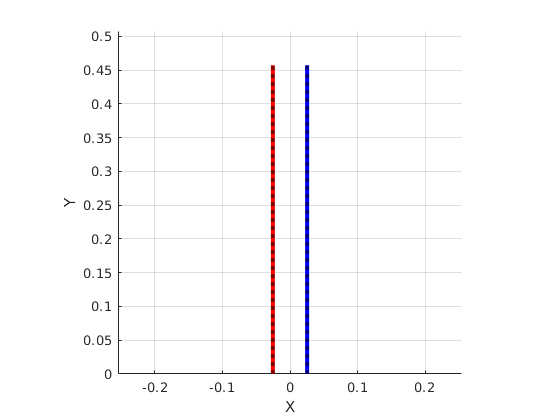

% Create arm object and initialize plotting
%planar_arm_obj = Arm2D(g_o, {g_o*g_o_A; g_o; g_o*g_o_B}, l_0, 'plot_unstrained', true);
planar_arm_obj = Arm2D(g_o, {g_o*g_o_A; g_o*g_o_B}, l_0, 'plot_unstrained', true);

muscle_o_real = copy(planar_arm_obj.muscle_o);
muscle_o_fit = copy(planar_arm_obj.muscle_o);

fig = figure();
line_options_muscles = struct("LineWidth", 3);

% Initialize plotting
planar_arm_obj.initialize_plotting(axes(fig), "line_options_muscles", line_options_muscles);

border_length_cm = 20 * 2.54;
ylim(planar_arm_obj.ax, [0, 1] * border_length_cm / 100);
xlim(planar_arm_obj.ax, [-0.5, 0.5] * border_length_cm / 100);

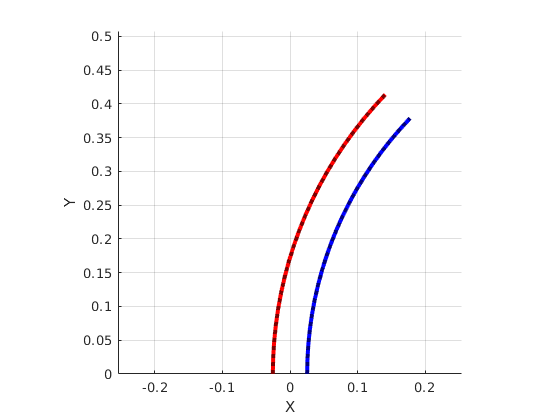

l_A = 18 * 0.0254;
l_B = 16.47 * 0.0254;
l_C = 0.1;
%v_l = [l_A; l_B; l_C];
v_l = [l_A;l_B];
planar_arm_obj.plot_unstrained = true;
planar_arm_obj.update_arm(v_l);

n_test_tags = 4;
i_test_tags = linspace(0, 1, n_test_tags);
muscle_ids = round(rand([1, n_test_tags])) + 1; % Randomly determined list of which muscles the tags are attached to

g_tags = cell(size(i_test_tags)); % Cell array for storing where the tags should be, on the arm
g_tags_meas = cell(size(i_test_tags)); % Cell array for storing measured tag positions, with random error

for i = 1 : n_test_tags
    t_i = i_test_tags(i);
    muscle_i = muscle_ids(i);
    g_tag_i = planar_arm_obj.muscles(muscle_i).g_0 * expm_se2(planar_arm_obj.muscles(muscle_i).h_tilde * t_i);
    g_random = SE2(diag([0.015, 0.015, pi/6]) * (2*rand([3, 1]) - 1));
    g_tag_meas_i = g_tag_i * g_random; % Random offset
    
    g_tags{i} = g_tag_i;
    g_tags_meas{i} = g_tag_meas_i;
end

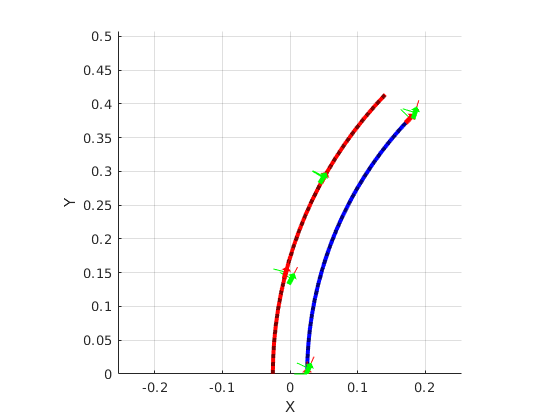

f_t_from_cells_g = @(cells_g) cell2mat( ...
    ... % Extract translation vectors from the pose cell arrays
    cellfun(@(mat) [mat(1:2, 3); 0], cells_g, 'uniformoutput', false) ... 
)';

f_quat_from_cells_g = @(cells_g) cell2mat( ...
    ... % Extract planar quaternions (complex numbers) from pose cell arrays
    ... % blkdiag creates a 3d rotmat about the z axis with the 2d rot mat
    cellfun(@(mat) rotm2quat(blkdiag(mat(1:2, 1:2), 1)), cells_g, 'uniformoutput', false)' ... 
);

t_tags = f_t_from_cells_g(g_tags);
quat_tags = f_quat_from_cells_g(g_tags);

t_tags_meas = f_t_from_cells_g(g_tags_meas);
quat_tags_meas = f_quat_from_cells_g(g_tags_meas);

tforms_plot_options = struct();
tforms_plot_options.framesize = rho * 0.75;
tforms_plot_options.parent = planar_arm_obj.ax;
tforms_plot_options.MeshFilePath = "tf_frame.stl";

t_tags_all = [t_tags; t_tags_meas];
quat_tags_all = [quat_tags; quat_tags_meas];

if exist("gh_tags", 'var')
    delete(gh_tags);
end
plotTransforms(t_tags, quat_tags, tforms_plot_options);
gh_tags = planar_arm_obj.ax.Children(1);

if exist("gh_tags_meas", 'var')
    delete(gh_tags_meas);
end
tforms_plot_options.meshcolor = "green";
plotTransforms(t_tags_meas, quat_tags_meas, tforms_plot_options);
gh_tags_meas = planar_arm_obj.ax.Children(1);

view([0, 90])

## Curve fitting

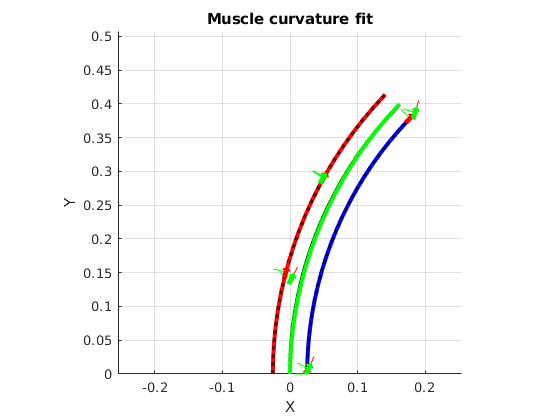

% Call the curve fit function
h_optim = curve_fit_2d(planar_arm_obj, g_tags_meas, i_test_tags, muscle_ids);

% Plot the fitted curvature
muscle_o_real.h_tilde = planar_arm_obj.muscle_o.h_tilde;
muscle_o_fit.h_tilde = h_optim;
muscle_o_fit.color = 'green';

muscle_o_real.plot_muscle(planar_arm_obj.ax, 'line_options', line_options_muscles);
muscle_o_fit.plot_muscle(planar_arm_obj.ax, 'line_options', line_options_muscles);
title("Muscle curvature fit")